clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip';
RT = load([Opt.LFolder, '\fit chip off.mat']);
B = load([Opt.LFolder, '\fit maxb1.mat']);

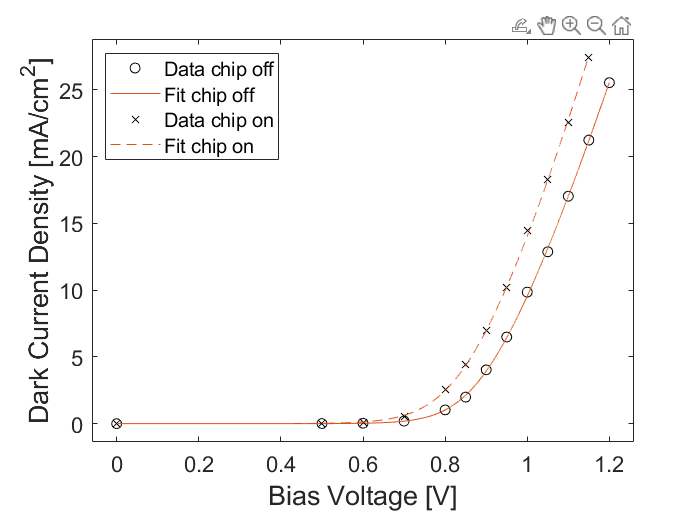

figure()
tL = tiledlayout('flow');
nexttile;
conv = 1000; % from A to mA
plot(RT.V_, RT.I_*conv, 'o', 'Color', 'black')
hold on
plot(RT.Vfit, RT.II*conv, 'Color', '#D95319')
plot(B.V_, B.I_*conv, 'x', 'Color', 'black')
plot(B.Vfit, B.II*conv, '--', 'Color', '#D95319')

lgd = legendFirstTile(tL, {'Data chip off', 'Fit chip off', 'Data chip on', 'Fit chip on'});
lgd.Location = "northwest";

xlim(setAxLim(RT.V_, 0.05));
ylim(setAxLim(B.I_*conv, 0.05))
grid off
legendFirstTile(tL);
labelAxesFig(tL, "Bias Voltage [V]", 'Dark Current Density [mA/cm^2]')
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, '_IV curve chip', '.png')

addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\SuSi\';
RT = load([Opt.LFolder, '\fit chip off.mat']);
B = load([Opt.LFolder, '\fit maxb1.mat']);

figure()
tL = tiledlayout('flow');
nexttile;
conv = 1000; % from A to mA
plot(RT.V_, RT.I_*conv, 'o', 'Color', 'black')
hold on
plot(RT.Vfit, RT.II*conv, 'Color', '#D95319')
plot(B.V_, B.I_*conv, 'x', 'Color', 'black')
plot(B.Vfit, B.II*conv, '--', 'Color', '#D95319')

lgd = legendFirstTile(tL, {'Data chip off', 'Fit chip off', 'Data chip on', 'Fit chip on'});
lgd.Location = "northwest";

xlim(setAxLim(RT.V_, 0.05));
ylim(setAxLim(B.I_*conv, 0.05))
grid off
legendFirstTile(tL);
labelAxesFig(tL, "Bias Voltage [V]", 'Dark Current Density [mA/cm^2]')
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, '_IV curve chip', '.png')